## Tutorial on Image Contrast

Objectives:

- understand how image contrast changes with MRI acquisition parameters

- optimise the image contrast for various applications

The code is organized into different sections. You can run the code of each session by simply pressing "ctrl+enter".

You can change various parameters and rerun the code following the instructions in the script.

*All "time" values will be given in ms

## Setting up

addpath('Functions');
addpath('Data');

## Exercise 9

The signal decay at time TE in MRI can be typically described as:


$$S\left(\textrm{TE}\right)=S_0 e^{-\frac{\textrm{TE}}{T_2 }}$$


Contrast between the two tissues at time TE is given by the following equation:


$$\mathrm{Contrast}\left(\mathrm{TE}\right)=S_{\mathrm{tissue1}} \left(\mathrm{TE}\right)-S_{\mathrm{tissue2}} \left(\mathrm{TE}\right)$$


First, run the following script without changing the parameter (using Ctrl+Enter)

close all

Specify the T2s of the tissues:

T2_tissue1 = 60; %ms
T2_tissue2 = 100; %ms

The time (TE) thats give maximum contrast:

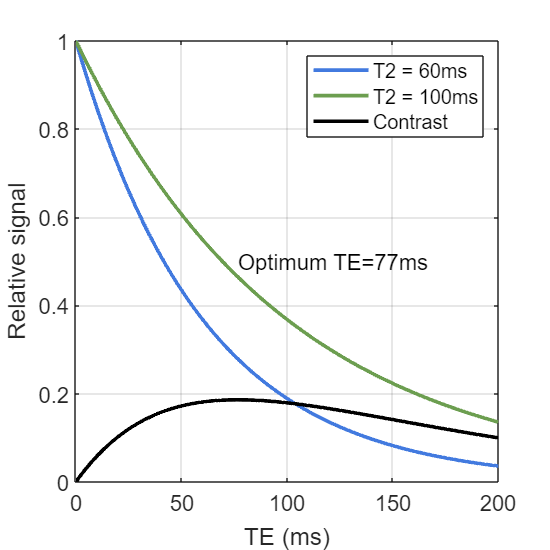

TEopt = simContrastvTE([T2_tissue1  T2_tissue2]);

What is the optimum TE?

Change T2_tissue1 to 50 ms and T2_tissue2 to 51 ms, and re-run the codes, what is the optimum TE?

Again, change T2_tissue1 to 60 ms and T2_tissue2 to 61 ms, what is the optimum TE? Do you notice when the T2s between the two tissues are very close, the optimum TE is exactly equal to T2?

Q1) If 2 tissues have the same T1 but different T2s (60 and 100ms respectively), what sequence parameters will give a stronger contrast?

**Challenge**

Can you analytically derive the optimum TE that produces the maximum contrast between two tissues with different T2 values?

Tip: Contrast is maximum when its slope is 0, and express the chante

## Exercise 10

Consider a sequence with a given TR and a Tissues with a given T1

Run the following codes (using Ctrl+Enter)

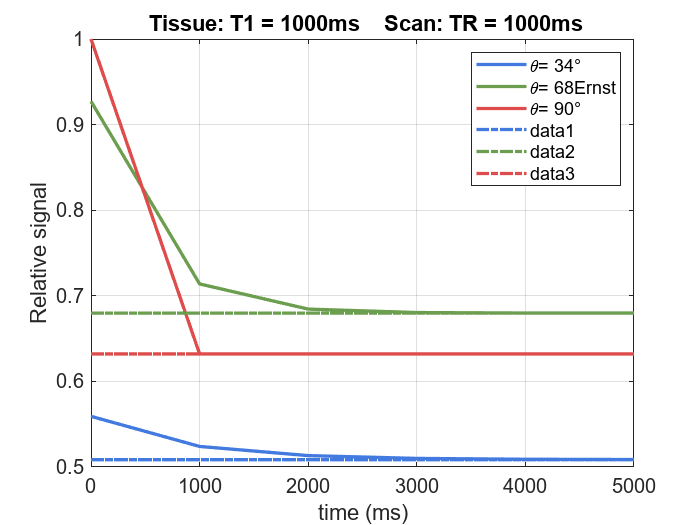

TR = 1000; %ms
T1 = 1000; %ms

simApproachSteadyState(T1,TR)

The red solid line represents the signal using flip angle of 90°, green line represents the Ernst angle signal and the blue line represents the signal using half of the Ernst angle. Dash lines show the levels when the signal becomes stable (steady-state). 

In the figure, which option produces the highest signal intensity after 10 RF excitations (i.e. 10*TR)?

Note that for 90°, at the second data point, the steady state is already reached. For smaller flip angles it takes longer ... this is why you are often reccomended to discard the first volumes of your functional experiment.

Increase the repetition time TR to 1000ms (and/or reduce to 250ms), does the Ernst angle (and its relative steady-state signal) stay the same?

**Challenge**

Can you derive the steady state signal using the figure in the tutorial? Have it as your homework :)

## Exercise 11

Q3) Grey matter has a T1=1330ms (@ 3T), if imaging with a TR=2000ms (standard fMRI TR), the flip angle that generates the maximum signal for that tissue is ~77°. 

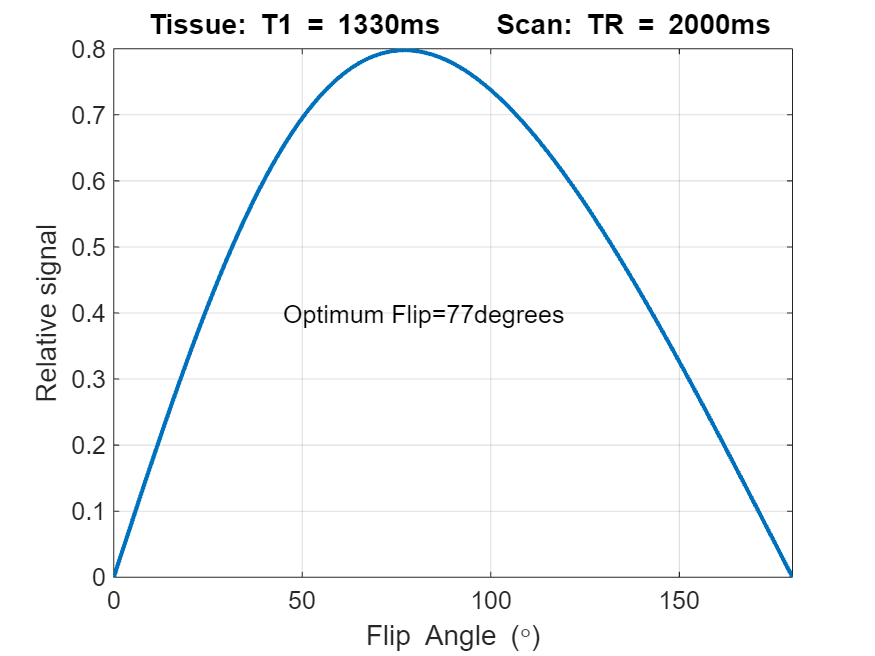

close all
TR = 2000; %ms

T1_gray_matter_3T =1330; %ms
simSignalvFlip(T1_gray_matter_3T,TR);%

If the tissue would have a longer T1 (for example if you would be imaging @ 7T), the optimum flip angle for the same TR would be:

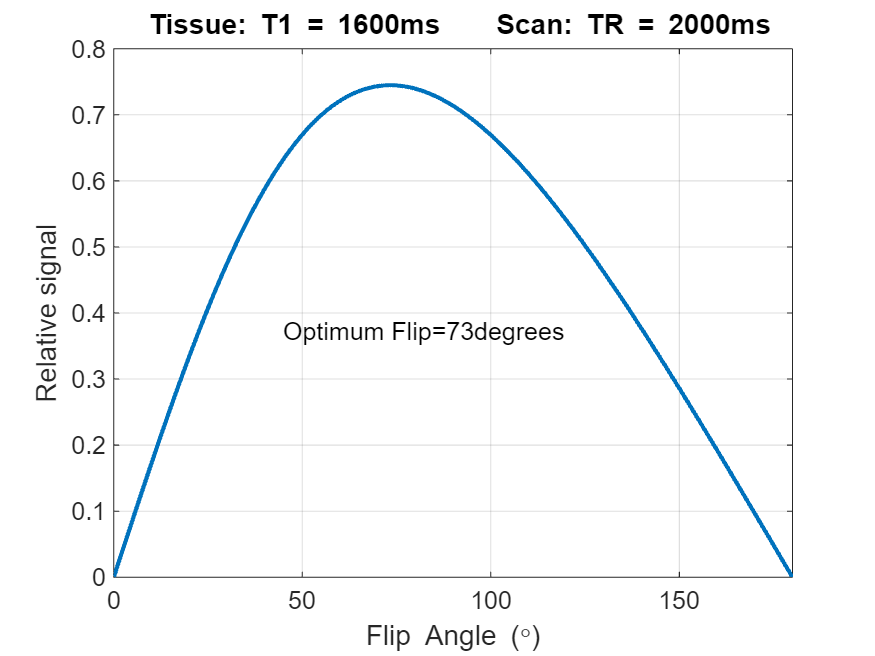

T1_gray_matter = 1600;
simSignalvFlip(T1_gray_matter,TR);

## Exercise 12

Q4) Grey matter has a T1=1330ms (@ 3T), and you were imaging it with a TR=3000ms, the flip angle that would generate the maximum signal for that tissue would be ~84°. If the sequence would be much faster (thanks to multiband 6), the flip angle should change to:

T1_gray_matter_3T = 1330; %ms

TR = 3000; %ms
simSignalvFlip(T1_gray_matter_3T,TR);% if TR is very large, the optimum signal is with 90degrees

TR = 500; %ms
simSignalvFlip(T1_gray_matter_3T,TR);% for a shorter TR the optimum slip angle is decreased

**Challenge**

Can you try to derive angle that gives the maximum signal for a given TR and T1 (Ernst angle)?

Meanwhile there is a function named ErnstAngle that you can call in the following way: [ FlipAngleDegrees ] = ErnstAngle(TR,T1)

You can check that this is always in agreement with the simulations.

## Exercise 13a

Q6) If two tissues have T1s of 700 and 1100ms (as WM and GM @3T), then the optimum contrast with TR = 3000ms is with a 90° flip. 

close all

T1_white_matter = 830; %ms
T1_gray_matter = 1330; %ms

TRLong = 3000; %ms
[~, ContrastTRLong]=simContrastvFlip([T1_white_matter T1_gray_matter],TRLong)


With TR = 60ms

TRShort = 60; %ms
[~, ContrastTRShort]=simContrastvFlip([T1_white_matter T1_gray_matter],TRShort)

As a bonus, you can check how a a brain image would look like with a parameter choice

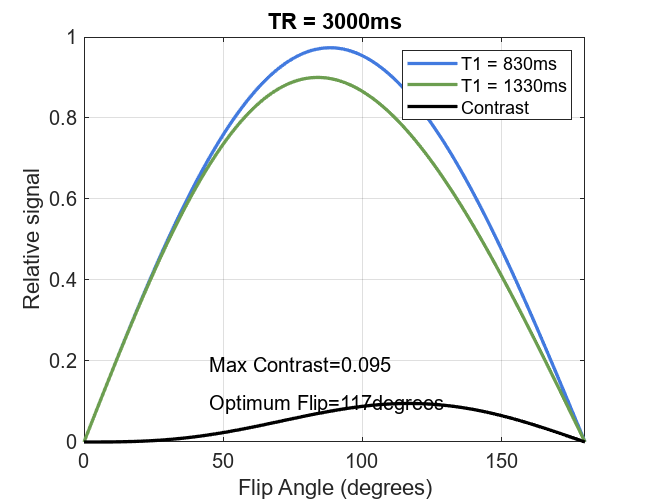

ContrastTRLong = 0.0951


TR          = 6; %ms

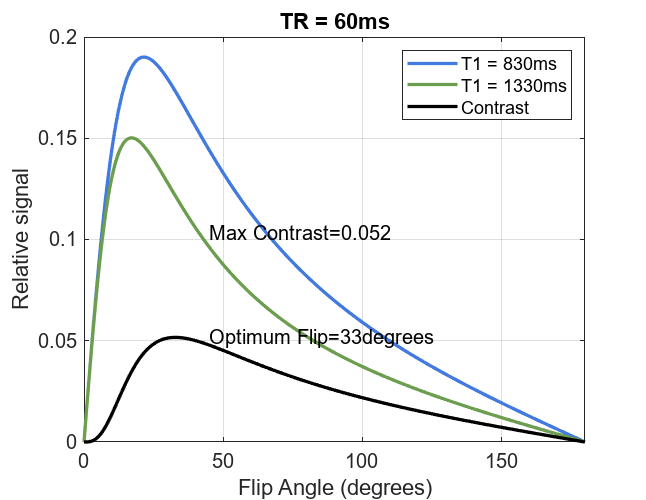

ContrastTRShort = 0.0517

TE          = 3; %ms
flipAngle   = 16; %degrees
B0 = 3; % here you can only add 3 or 7 (Tesla)



simContrast(0,TR,TE,flipAngle,B0)

## Exercise 13b

The question mentioned per unit of time, it means that you will be comparing sequences acquired in the same total amount of time.

In a fantasy MRI world, where noise doesn't exist, such comparison is trivial because no matter how many times we repeat the measurement the contrast won't change, i.e. TR = 600ms and TR = 6ms always produce the same signal differences (0.095 and 0.052).

Unfortunately, MRI is quite a noisy imaging modality so we have to take the measurment noise into account when we comparing the contast. One way to doing this is called contrast-to-noise ratio:

- CNR = contrast / noise in the measurment

This shows how much differences we can observe in the presence of noise.

Each time you do a measurement and add it to the previously acquired signal, you expect the signal to add coherently (it should always have the same value and phase), while the noise of each measurement should be independent/orthogonal.

For this reason when you average multiple measurements your SNR increases with the square root of the number of measurements (i.e. the noise in the measurement reduced). One way to introduce this concept is to divide the contrast by the square root of the repetition time.

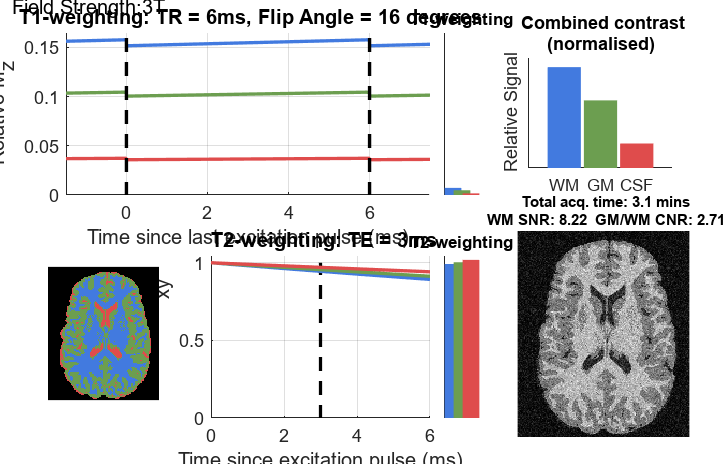

ContrastTRLong = 0.1524

ContrastTRShort = 0.0163

EffectiveContrastTRLong = 0.0062

EffectiveContrastTRShort = 0.0067

ContrastTRLong
ContrastTRShort


EffectiveContrastTRLong = ContrastTRLong/sqrt(TRLong)
EffectiveContrastTRShort = ContrastTRShort/sqrt(TRShort)
